% Sets the max iterations you want to run through
maxTime = 500;
maxSims = 10000;
pos = zeros(1,maxTime);
bestPos = zeros(1,maxTime);
targetPosSaver = zeros(1,maxTime);
timesteps = 1:maxTime;
error = zeros(1,maxTime);
integ = 0;
posPrev = 0;
posCur = 0;
velCur = 0;
bestCoefError = 999999999;

bestKp = rand;
bestKi = rand;
bestKd = rand*2;

for sims = 1:maxSims

    % These are the coefficients that tweak how our PID works which we are
    % randomly generating as a number between 0 and 2
    Kp = bestKp + (rand-0.5)*.5;
    Ki = bestKi + (rand-0.5)*.5;
    Kd = bestKd + (rand-0.5)*.5;

    [pos,error,targetPosSaver] = PIDrunner(Kp,Ki,Kd,1,maxTime,0,0);

    absError = abs(error);
    avgError = mean(absError);

    if avgError < bestCoefError
        bestCoefError = avgError;
        bestKp = Kp;
        bestKi = Ki;
        bestKd = Kd;
        bestPos = pos;
        bestError = absError;
    end

end

bestCoefError

bestCoefError = 0.6214

bestKp

bestKp = 0.3206

bestKi

bestKi = 0.1416

bestKd

bestKd = 0.8628

bestPos

bestPos =          0    7.5108   29.0276   55.9903   74.2571   76.8681   68.4514   59.3784   56.6982   59.8842   63.6093   63.5591   59.8275   55.7711   54.4183   56.0008   58.3688   59.2596   58.1203   56.1108   54.7278   54.5063   54.8315   54.7386   53.8005   52.3587   51.0686   50.2982   49.9077   49.4951   48.7939   47.8618   46.9583   46.2875   45.8490   45.4914   45.0758   44.5877   44.1199   43.7711   43.5644   43.4464   43.3487   43.2455   43.1623   43.1398   43.1943   43.3075   43.4465   43.5913


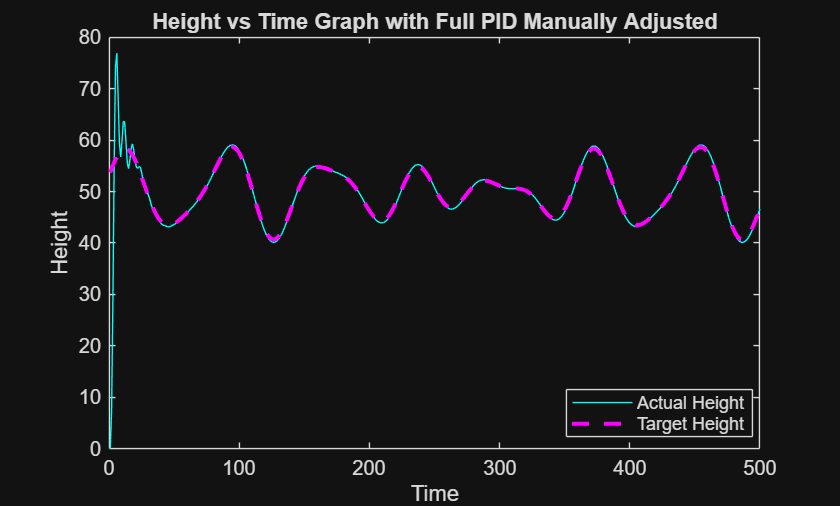


% This plots both the target height and actual height
plot(timesteps,bestPos,'cyan-')
hold on
plot(timesteps,targetPosSaver,"magenta--",LineWidth=2)
title("Height vs Time Graph with Full PID Manually Adjusted")
xlabel("Time")
ylabel("Height")
legend("Actual Height","Target Height")
legend(["Actual Height", "Target Height"], "Position", [0.6744 0.1362 0.2220, 0.0924])
hold off

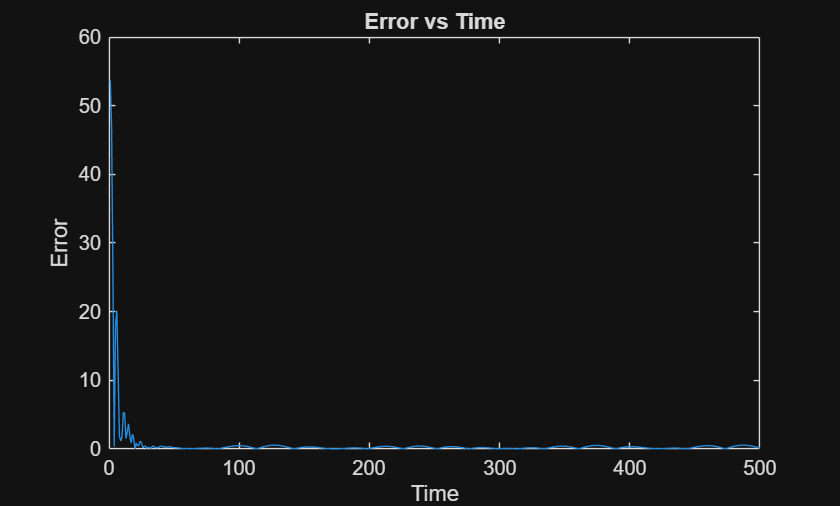

plot(timesteps,bestError)
title("Error vs Time")
xlabel("Time")
ylabel("Error")

clear
clc